# Mori-Tanaka Method

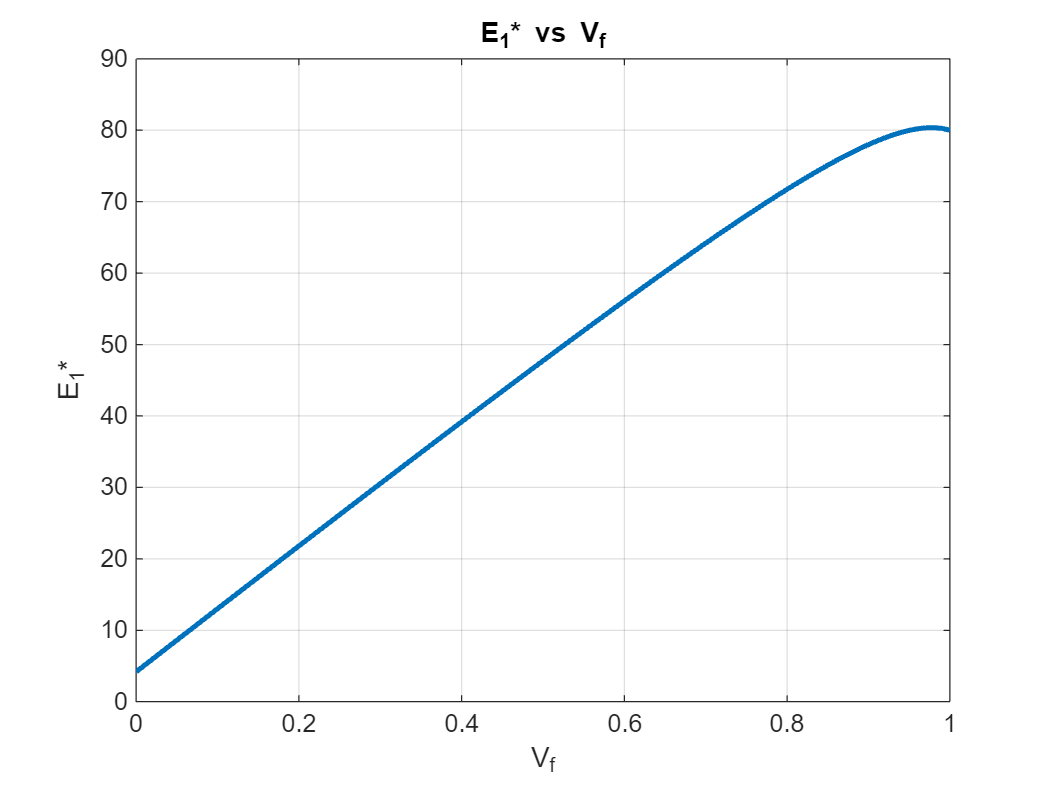

clc;clear;
syms Vf
Vf_val = linspace(0,1,101);

E_f = 80;
G_f = 33.33;
v_f = 0.2;

S_f = [1/E_f, -v_f/E_f, -v_f/E_f, 0, 0, 0;
       -v_f/E_f, 1/E_f, -v_f/E_f, 0, 0, 0;
       -v_f/E_f, -v_f/E_f, 1/E_f, 0, 0, 0;
       0, 0, 0, 1/G_f, 0, 0;
       0, 0, 0, 0, 1/G_f, 0;
       0, 0, 0, 0, 0, 1/G_f;];
C_f = inv(S_f);

E_m = 4.2;
v_m = 0.34;
G_m = E_m/(2*(1+v_m));

S_m = [1/E_m, -v_m/E_m, -v_m/E_m, 0, 0, 0;
       -v_m/E_m, 1/E_m, -v_m/E_m, 0, 0, 0;
       -v_m/E_m, -v_m/E_m, 1/E_m, 0, 0, 0;
       0, 0, 0, 1/G_m, 0, 0;
       0, 0, 0, 0, 1/G_m, 0;
       0, 0, 0, 0, 0, 1/G_m;];
C_m = inv(S_m);

% fiber
syms n_f m_f k_f l_f p_f
eqn1 = n_f == C_f(1,1);
eqn2 = l_f == C_f(1,2);
eqn3 = k_f + m_f == C_f(2,2);
eqn4 = m_f == C_f(4,4);
eqn5 = p_f == C_f(5,5);

fiber = solve([eqn1,eqn2,eqn3,eqn4,eqn5],[n_f,l_f,k_f,m_f,p_f]);
n_f = double(fiber.n_f);
m_f = double(fiber.m_f);
k_f = double(fiber.k_f);
l_f = double(fiber.l_f);
p_f = double(fiber.p_f);

% matrix
syms n_m m_m k_m l_m p_m
eqn1 = n_m == C_m(1,1);
eqn2 = l_m == C_m(1,2);
eqn3 = k_m + m_m == C_m(2,2);
eqn4 = m_m == C_m(4,4);
eqn5 = p_m == C_m(5,5);

matrix = solve([eqn1,eqn2,eqn3,eqn4,eqn5],[n_m,l_m,k_m,m_m,p_m]);
n_m = double(matrix.n_m);
m_m = double(matrix.m_m);
k_m = double(matrix.k_m);
l_m = double(matrix.l_m);
p_m = double(matrix.p_m);

% composite 
k_c = (Vf*k_f*(k_m + m_m) + (1-Vf)*k_m*(k_f + m_m))/(Vf*(k_m + m_m) + (1-Vf)*(k_f + m_m));
l_c = (Vf*l_f*(k_m + m_m) + (1-Vf)*l_m*(k_f + m_m))/(Vf*(k_m + m_m) + (1-Vf)*(k_f + m_m));
n_c = (1-Vf)*n_m + Vf*n_f + (1-Vf)*Vf*(l_f-l_m)^2/(Vf*(k_m + m_m) + (1-Vf)*(k_f + m_m));
m_c = (m_f*m_m*(k_m+2*m_m)+Vf*m_f*k_m*m_m+(1-Vf)*m_m^2*k_m)/(k_m*m_m+(k_m+2*m_m)*(Vf*m_m+(1-Vf)*m_f));
p_c = p_m*(p_f*(1+Vf) + p_m*(1-Vf))/(p_f*(1-Vf) + p_m*(1+Vf));

C_c = [n_c, l_c, l_c, 0, 0, 0;
       l_c, k_c+m_c, k_c-m_c, 0, 0, 0;
       l_c, k_c-m_c, k_c+m_c, 0, 0, 0;
       0, 0, 0, m_c, 0, 0;
       0, 0, 0, 0, p_c, 0;
       0, 0, 0, 0, 0, p_c;];

S_c = inv(C_c);

%E1
E1_c = 1/S_c(1,1);
E1_c_val = double(subs(E1_c,Vf_val));

%E2
E2_c = 1/S_c(2,2);
E2_c_val = double(subs(E2_c,Vf_val));

%v12
v12_c = -S_c(1,2)*E1_c;
v12_c_val = double(subs(v12_c,Vf_val));

%v23
v23_c = -S_c(2,3)*E2_c;
v23_c_val = double(subs(v23_c,Vf_val));

%G12
G12_c = 1/S_c(5,5);
G12_c_val = double(subs(G12_c,Vf_val));

%G23
G23_c = 1/S_c(4,4);
G23_c_val = double(subs(G23_c,Vf_val));

%plot
figure;
plot(Vf_val, E1_c_val, 'LineWidth', 2);
title('E_1* vs V_f');
xlabel('V_f'); ylabel('E_1*');
grid on;

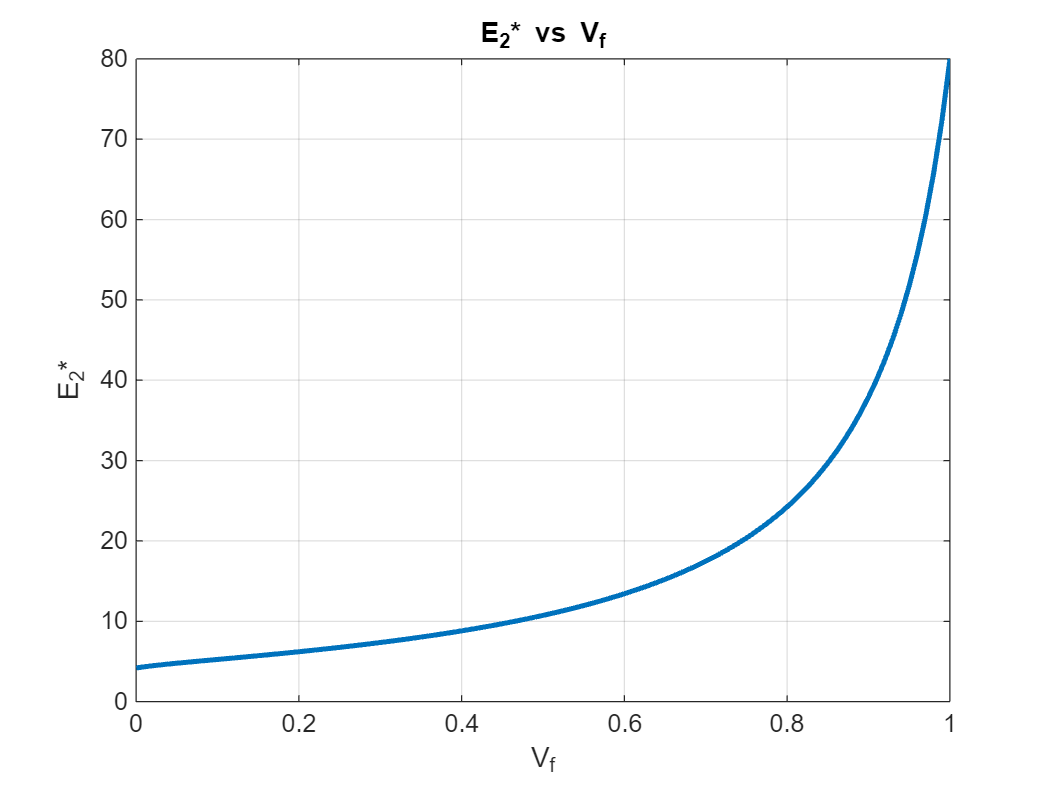


figure;
plot(Vf_val, E2_c_val, 'LineWidth', 2);
title('E_2* vs V_f');
xlabel('V_f'); ylabel('E_2*');
grid on;

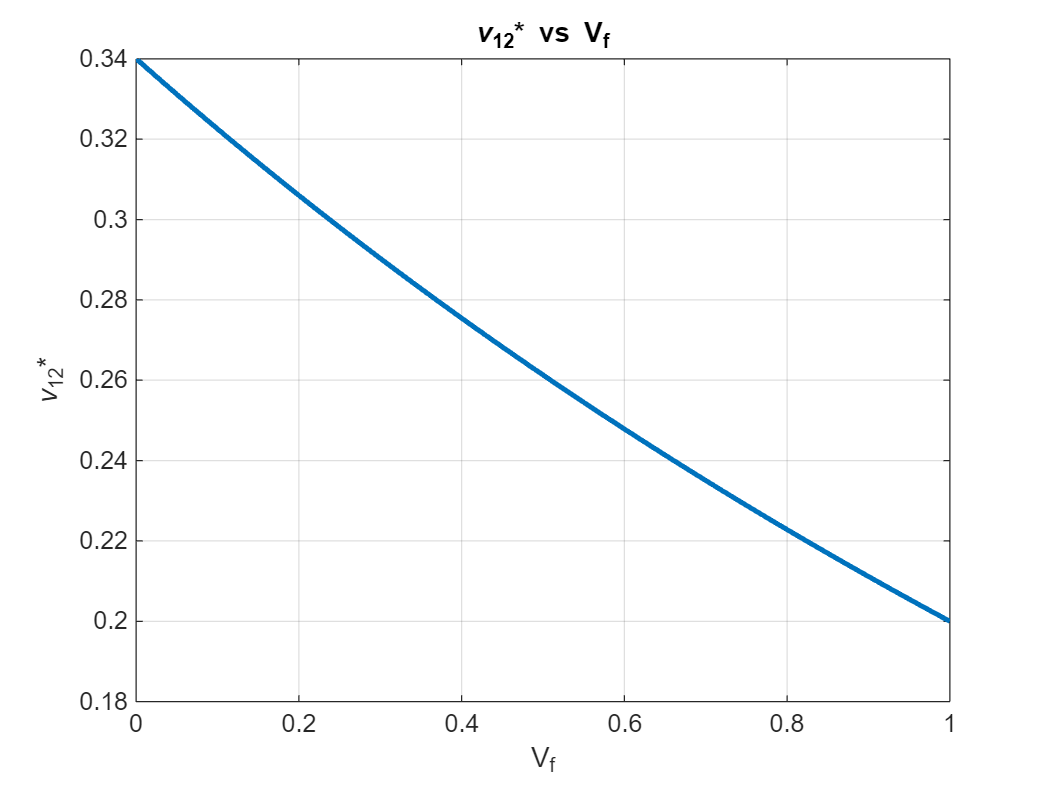


figure;
plot(Vf_val, v12_c_val, 'LineWidth', 2);
title('\nu_{12}* vs V_f');
xlabel('V_f'); ylabel('\nu_{12}*');
grid on;

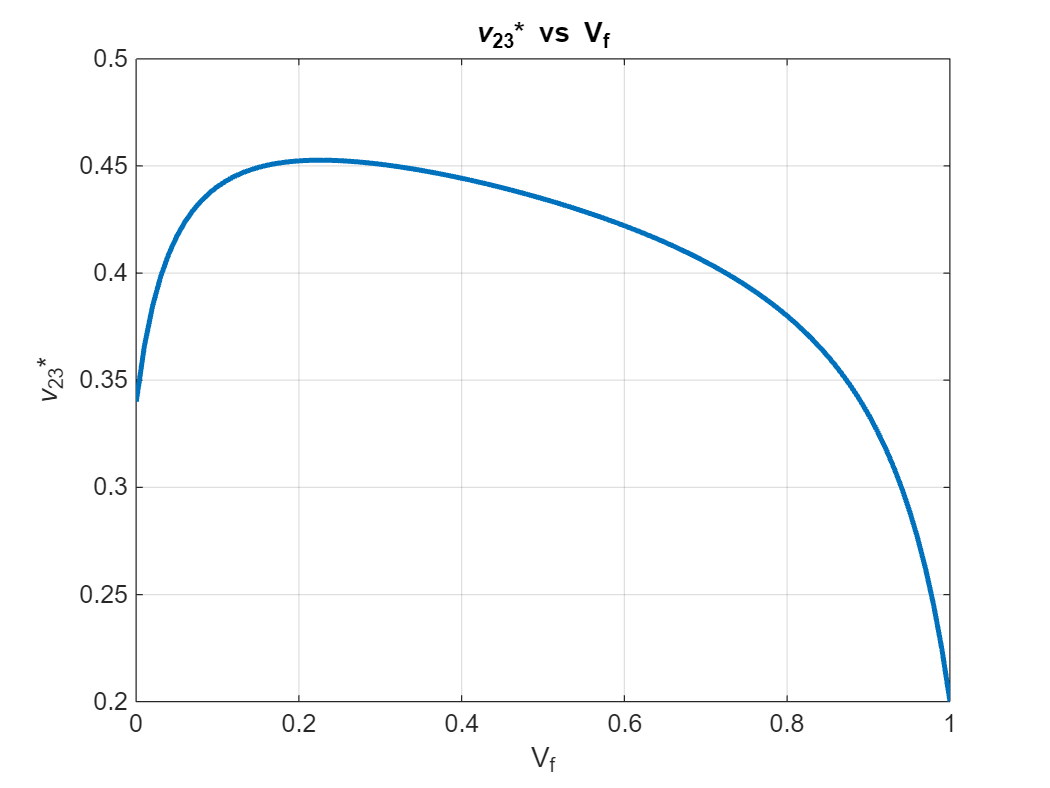


figure;
plot(Vf_val, v23_c_val, 'LineWidth', 2);
title('\nu_{23}* vs V_f');
xlabel('V_f'); ylabel('\nu_{23}*');
grid on;

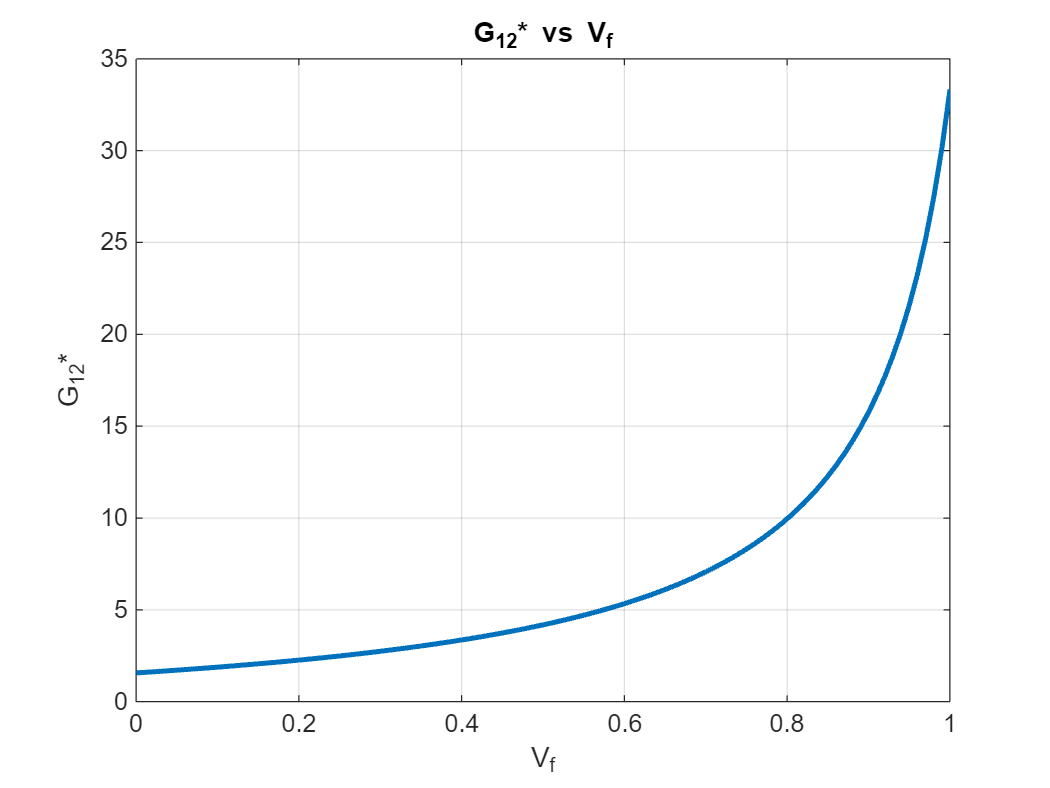


figure;
plot(Vf_val, G12_c_val, 'LineWidth', 2);
title('G_{12}* vs V_f');
xlabel('V_f'); ylabel('G_{12}*');
grid on;

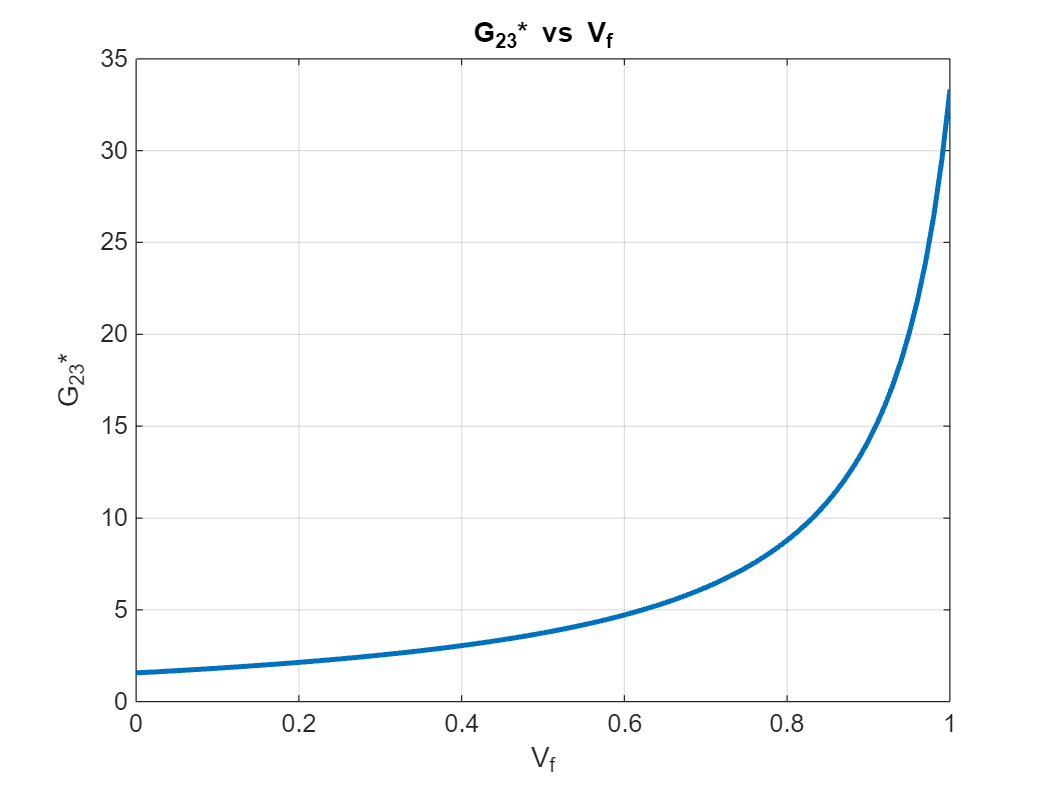


figure;
plot(Vf_val, G23_c_val, 'LineWidth', 2);
title('G_{23}* vs V_f');
xlabel('V_f'); ylabel('G_{23}*');
grid on;